# Exploratory Data Analysis (TS03 - Month 2 Visit)

## Initialization - Data Setup

Import the processed data obtained from Tourette Graphical User Interface programs (SyncData and renderData). The processed data will contain time matched data for easy visualization. 

clear;clc;close all;
cd('G:\TS03\2016_11_07');
%cd('C:\Users\jcagle\Documents\Brain Mapping Laboratory\TS03\2016_11_07')
TrialID = dir('Processed*.mat');
for trial = 1:length(TrialID)
    ProcessedData(trial) = load(TrialID(trial).name);
    TaskID{trial} = TrialID(trial).name(31:end-4);
end

SignalType = 'ThaData';

## Tic Prevalence Analysis

This section will look into how often does tic occur during the full recording period. Only periods containing DBS recording are considered in this case. 

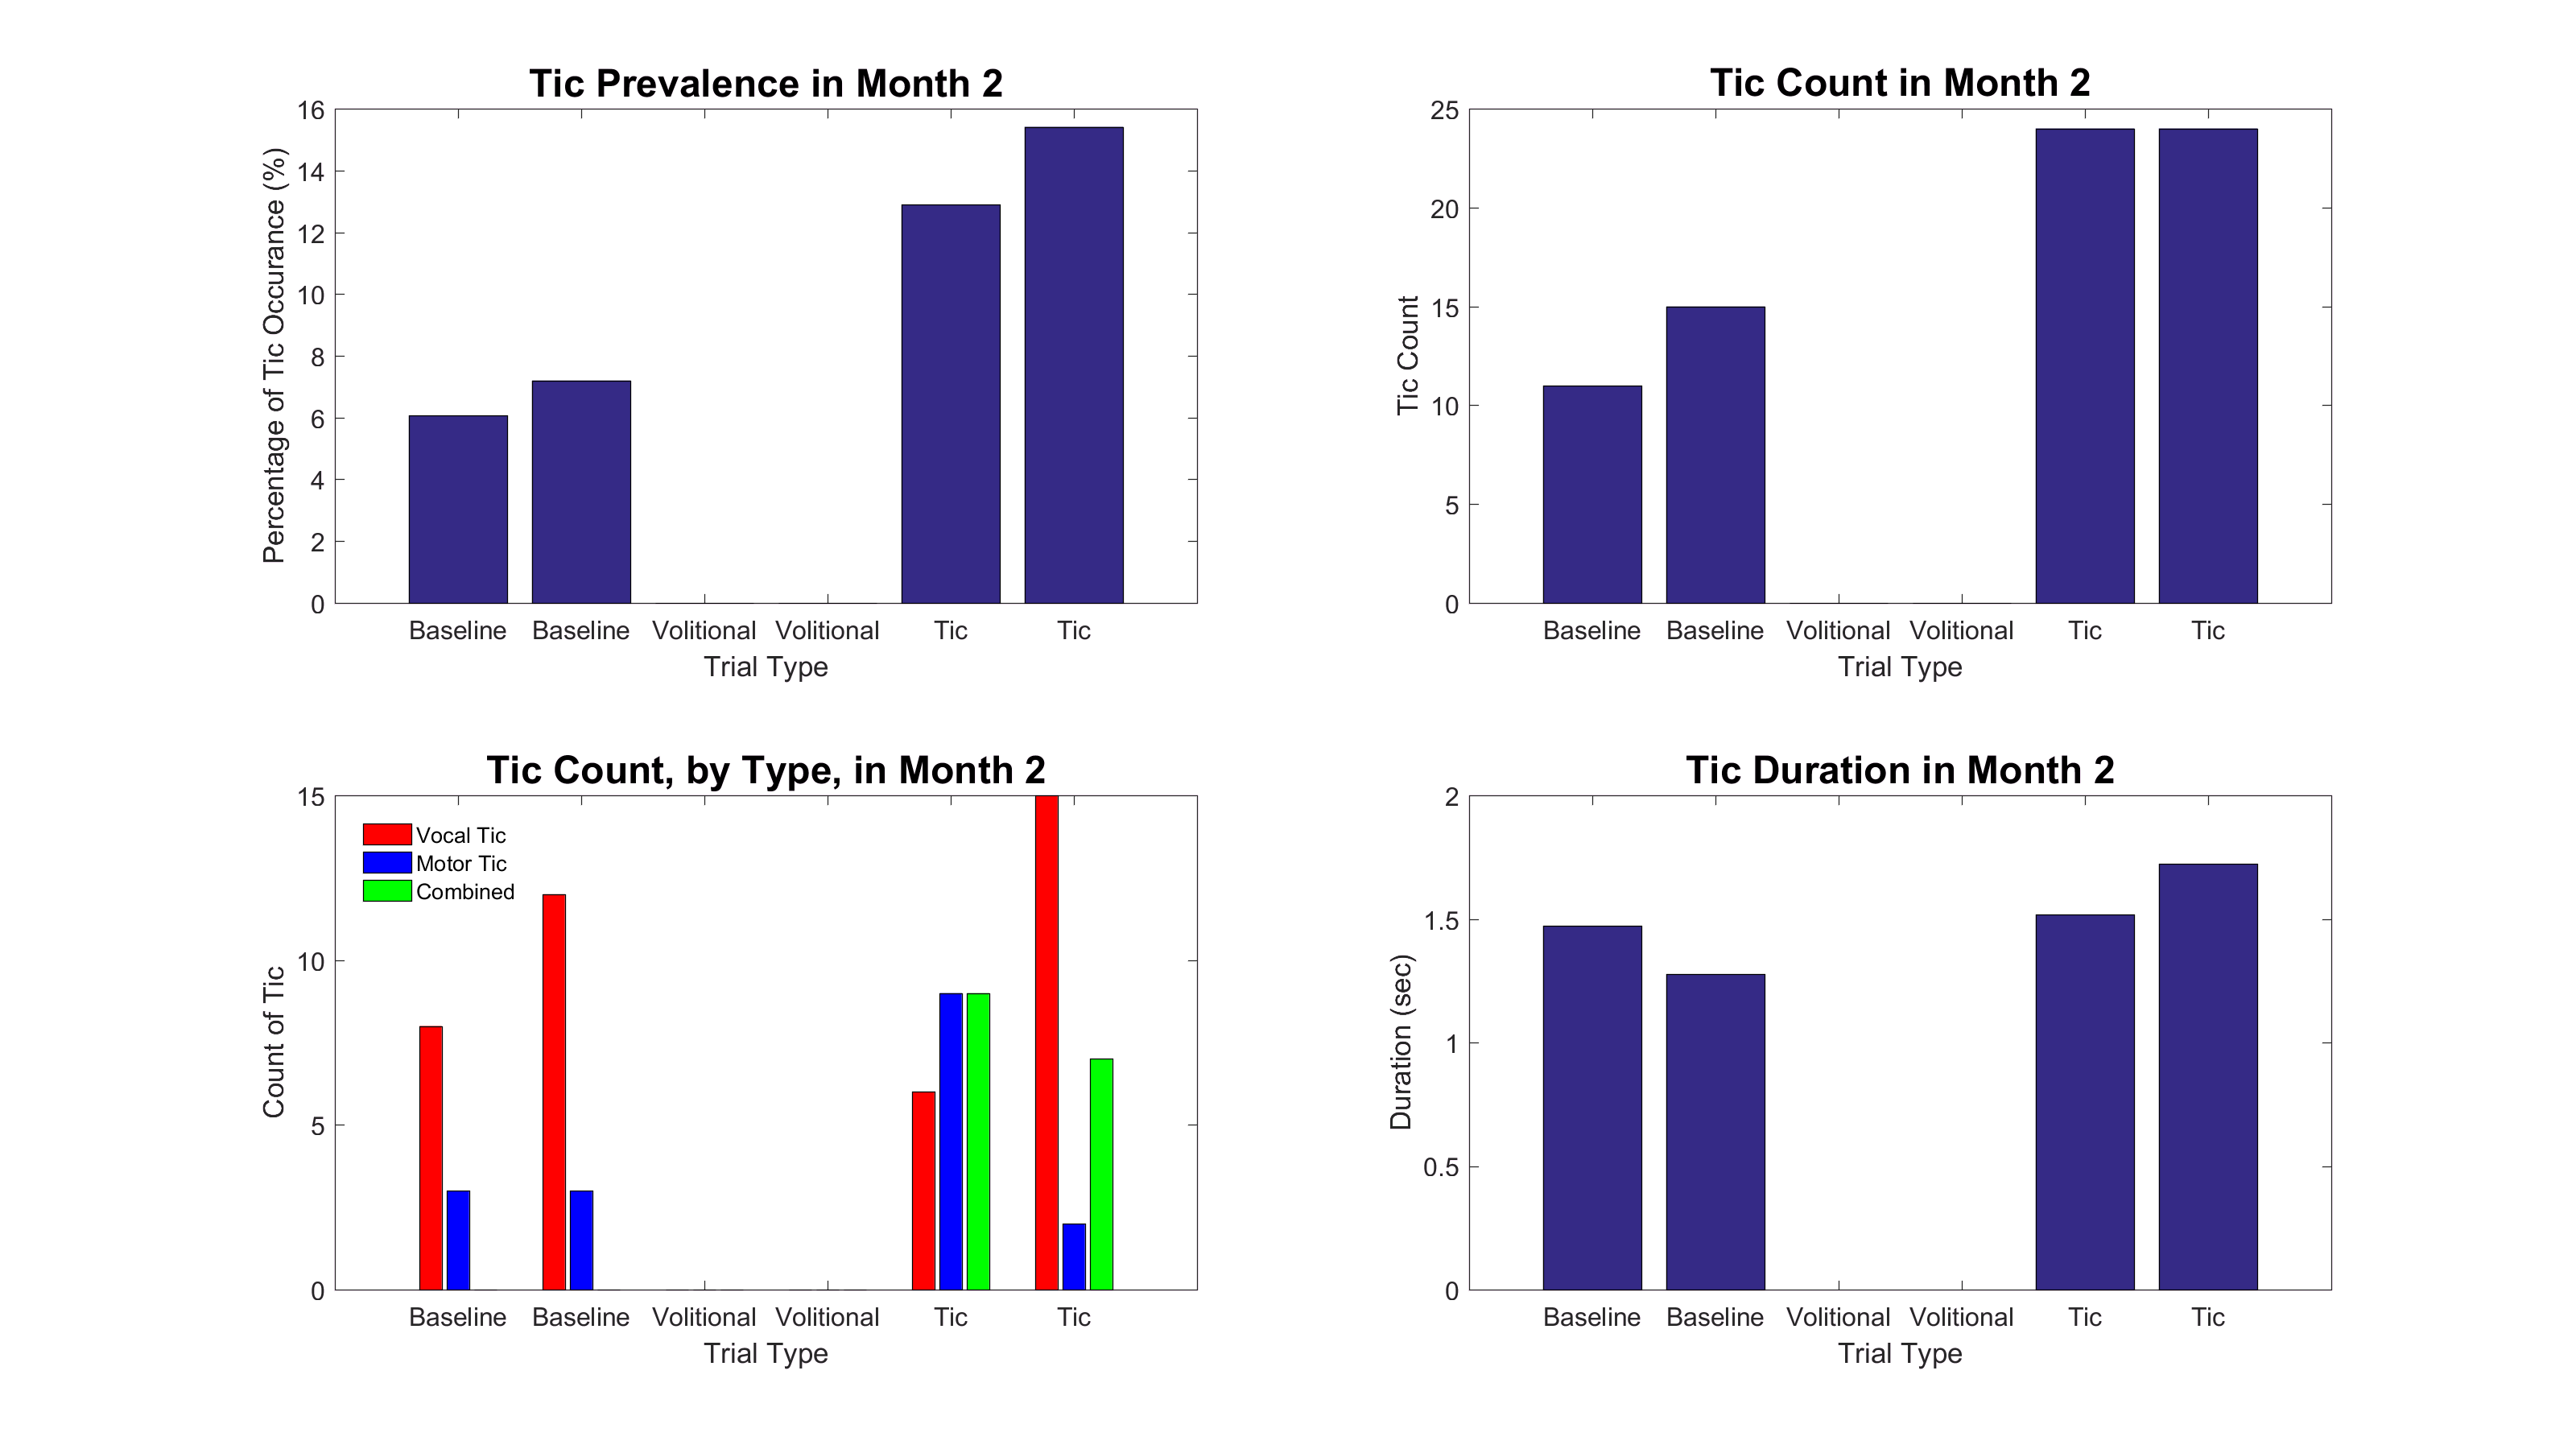

% Compute the Tic Parameters 
TicPercentage = zeros(1,length(ProcessedData));
TicType = zeros(length(ProcessedData),3);
AverageTicDuration = zeros(length(ProcessedData),1);
for trial = 1:length(ProcessedData)
    DBS_RecordingTime = [-max(ProcessedData(trial).DBS_Bias) -min(ProcessedData(trial).DBS_Bias)+max(ProcessedData(trial).Left_DBS.TimeRange)];
    PeriodSelection = ProcessedData(trial).Marker.time - ProcessedData(trial).EMG_Bias > DBS_RecordingTime(1) & ...
        ProcessedData(trial).Marker.time - ProcessedData(trial).EMG_Bias < DBS_RecordingTime(2);
    TicPercentage(trial) = sum(ProcessedData(trial).Marker.data(PeriodSelection) ~= 0) / sum(PeriodSelection);
    
    TicRecording(trial).Count = 0;
    EndIndex = 0;
    while true
        Index = find(ProcessedData(trial).Marker.data(EndIndex+1:end) ~= 0, 1) + EndIndex;
        EndIndex = find(ProcessedData(trial).Marker.data(Index+1:end) == 0, 1) + Index;
        if isempty(Index)
            break;
        end
        TicRecording(trial).Count = TicRecording(trial).Count + 1;
        TicRecording(trial).Type(TicRecording(trial).Count) = ProcessedData(trial).Marker.data(Index);
        TicRecording(trial).Duration(TicRecording(trial).Count) = ProcessedData(trial).Marker.time(EndIndex) - ProcessedData(trial).Marker.time(Index);
        TicRecording(trial).Onset(TicRecording(trial).Count) = ProcessedData(trial).Marker.time(Index) - ProcessedData(trial).EMG_Bias;
        TicRecording(trial).OnsetIndex(TicRecording(trial).Count) = Index;
    end
    
    TicType(trial,1) = sum(TicRecording(trial).Type == 1);
    TicType(trial,2) = sum(TicRecording(trial).Type == 2);
    TicType(trial,3) = sum(TicRecording(trial).Type == 3);
    AverageTicDuration(trial) = mean(TicRecording(trial).Duration);
end

% Visualization
largeFigure(0, [1600 900]); clf; hold on;
subplot(2,2,1); cla;
bar(1:length(ProcessedData), TicPercentage * 100);
xlabel('Trial Type','fontsize',13);
ylabel('Percentage of Tic Occurance (%)','fontsize',13);
set(gca,'XTick',1:length(ProcessedData),'XTickLabel',TaskID);
set(gca,'FontSize',12);
title('Tic Prevalence in Month 2','fontsize',18);

subplot(2,2,2); cla;
bar(1:length(ProcessedData), [TicRecording.Count]);
xlabel('Trial Type','fontsize',13);
ylabel('Tic Count','fontsize',13);
set(gca,'XTick',1:length(ProcessedData),'XTickLabel',TaskID);
set(gca,'FontSize',12);
title('Tic Count in Month 2','fontsize',18);

subplot(2,2,3); cla;
hb = bar(1:length(ProcessedData), TicType, 'grouped');
set(hb(1), 'FaceColor','r')
set(hb(2), 'FaceColor','b')
set(hb(3), 'FaceColor','g')
xlabel('Trial Type','fontsize',13);
ylabel('Count of Tic','fontsize',13);
set(gca,'XTick',1:length(ProcessedData),'XTickLabel',TaskID);
set(gca,'FontSize',12);
legendFont(gca,{'Vocal Tic','Motor Tic','Combined'},{'fontsize',10,'location','northwest'});
title('Tic Count, by Type, in Month 2','fontsize',18);

subplot(2,2,4); cla;
bar(1:length(ProcessedData), AverageTicDuration);
xlabel('Trial Type','fontsize',13);
ylabel('Duration (sec)','fontsize',13);
set(gca,'XTick',1:length(ProcessedData),'XTickLabel',TaskID);
set(gca,'FontSize',12);
title('Tic Duration in Month 2','fontsize',18);

***Results:***

The "Volitional" trials are not labeled yet. The patient seems to have less tic during "Baseline" trial, which is when we instructed her to control her tic as much as possible. On the other hand, during "Tic" trial, she develop more Tic. This is as expected. From the graphical representation, it seems she is capable of controlling half of her tic by active suppression. Whether 14% of the time having Tic is a high number or not depends on the Clinician feedback. 

The tic is highly prevalence in vocal tic. This is often seen as sniffing of nose accompany with tremoring. There are not any combined Tic during baseline, the patient is capable of suppressing most of her motor symptoms but not so much for the vocal symptoms. The duration, on the other hand, remain mostly the same whether suppressing or not.

## Tic Onset Computation

In this section, we will try to sector out snippets of Tic recording in the recording. Since we found out that the average Tic duration is around 1 second, we are going to sector out data from 5 seconds before Tic to 5 seconds after Tic. This onset analysis consider all three type of tic identified in previous section as the same tic to simplify the analysis.

The criteria during this analysis is to store both Left Device and Right Device together for combined visualization. However, since there are time-shift for the Left and Right recording, In addition, a variable named **TicRecording.DataCompletion **will indicate whether the signal is completed or not. 

- 0 - No Data Available

- 1 - Only the first part contain data, the rest are 0s

- 2 - Only the last part contain data, the initials are 0s

- 3 - Contain All Data

% Compute the Tic Onset Structure

TimeLimit = [-5 5];

for trial = 1:length(ProcessedData)
    IndexRange = ProcessedData(trial).Right_DBS.SamplingRate*TimeLimit(1):ProcessedData(trial).Right_DBS.SamplingRate*TimeLimit(2);
    TicRecording(trial).ThaData = zeros(length(IndexRange),TicRecording(trial).Count,2);
    TicRecording(trial).CorData = zeros(length(IndexRange),TicRecording(trial).Count,2);
    TicRecording(trial).DataCompletion = zeros(TicRecording(trial).Count,2);
    for TicID = 1:TicRecording(trial).Count
        [TD,OnsetIndex] = min(abs(ProcessedData(trial).Left_DBS.TimeRange - ProcessedData(trial).DBS_Bias(1) - TicRecording(trial).Onset(TicID)));
        if TD > 0.1
            OnsetIndex = [];
        end
        if ~isempty(OnsetIndex)
            if OnsetIndex + IndexRange(end) >= length(ProcessedData(trial).Left_DBS.data)
                TicRecording(trial).ThaData(1:end-(OnsetIndex+IndexRange(end)-length(ProcessedData(trial).Left_DBS.data)),TicID,1) = ProcessedData(trial).Left_DBS.data(OnsetIndex + IndexRange(1) : end , 1);
                TicRecording(trial).CorData(1:end-(OnsetIndex+IndexRange(end)-length(ProcessedData(trial).Left_DBS.data)),TicID,1) = ProcessedData(trial).Left_DBS.data(OnsetIndex + IndexRange(1) : end , 3);
                TicRecording(trial).DataCompletion(TicID,1) = 1;
            elseif OnsetIndex + IndexRange(1) <= 1
                TicRecording(trial).ThaData(end-OnsetIndex-IndexRange(end)+1:end,TicID,1) = ProcessedData(trial).Left_DBS.data(1 : OnsetIndex + IndexRange(end) , 1);
                TicRecording(trial).CorData(end-OnsetIndex-IndexRange(end)+1:end,TicID,1) = ProcessedData(trial).Left_DBS.data(1 : OnsetIndex + IndexRange(end) , 3);
                TicRecording(trial).DataCompletion(TicID,1) = 2;
            else
                TicRecording(trial).ThaData(:,TicID,1) = ProcessedData(trial).Left_DBS.data(OnsetIndex + IndexRange , 1);
                TicRecording(trial).CorData(:,TicID,1) = ProcessedData(trial).Left_DBS.data(OnsetIndex + IndexRange , 3);
                TicRecording(trial).DataCompletion(TicID,1) = 3;
            end
        end
        
        [TD,OnsetIndex] = min(abs(ProcessedData(trial).Right_DBS.TimeRange - ProcessedData(trial).DBS_Bias(2) - TicRecording(trial).Onset(TicID)));
        if TD > 0.1
            OnsetIndex = [];
        end
        if ~isempty(OnsetIndex)
            if OnsetIndex + IndexRange(end) >= length(ProcessedData(trial).Right_DBS.data)
                TicRecording(trial).ThaData(1:end-(OnsetIndex+IndexRange(end)-length(ProcessedData(trial).Left_DBS.data)),TicID,2) = ProcessedData(trial).Right_DBS.data(OnsetIndex + IndexRange(1) : end , 1);
                TicRecording(trial).CorData(1:end-(OnsetIndex+IndexRange(end)-length(ProcessedData(trial).Left_DBS.data)),TicID,2) = ProcessedData(trial).Right_DBS.data(OnsetIndex + IndexRange(1) : end , 3);
                TicRecording(trial).DataCompletion(TicID,2) = 1;
            elseif OnsetIndex + IndexRange(1) <= 1
                TicRecording(trial).ThaData(end-OnsetIndex-IndexRange(end)+1:end,TicID,2) = ProcessedData(trial).Right_DBS.data(1 : OnsetIndex + IndexRange(end) , 1);
                TicRecording(trial).CorData(end-OnsetIndex-IndexRange(end)+1:end,TicID,2) = ProcessedData(trial).Right_DBS.data(1 : OnsetIndex + IndexRange(end) , 3);
                TicRecording(trial).DataCompletion(TicID,2) = 2;
            else
                TicRecording(trial).ThaData(:,TicID,2) = ProcessedData(trial).Right_DBS.data(OnsetIndex + IndexRange , 1);
                TicRecording(trial).CorData(:,TicID,2) = ProcessedData(trial).Right_DBS.data(OnsetIndex + IndexRange , 3);
                TicRecording(trial).DataCompletion(TicID,2) = 3; 
            end
        end
    end
end

We can utilize a graphical user interface program to select the Baseline Segments and reject trials/tic that does not have enough data. 

% Obtain Baseline
[TicRecording, Baseline] = TicAnalyzer(ProcessedData, TicRecording, TaskID, 1);

% Compute Power Spectral Density
Frequency = 0:0.1:30;
TimeRange = (ProcessedData(trial).Right_DBS.SamplingRate*TimeLimit(1):ProcessedData(trial).Right_DBS.SamplingRate*TimeLimit(2)) / ProcessedData(1).Right_DBS.SamplingRate;

PreTic = IndexRange < 0;
PostTic = IndexRange >= 0;
Pxx_Pre = cell(1,length(TicRecording));
Pxx_Post = cell(1,length(TicRecording));
Spect_Left = cell(1,length(TicRecording));
Spect_Right = cell(1,length(TicRecording));
for trial = 1:length(TicRecording)
    Fs = ProcessedData(trial).Left_DBS.SamplingRate;
    Window = Fs; 
    Overlap = Fs/8*7;
    SpectBin = floor((length(IndexRange)-Window)/round(Window-Overlap));
    mem_params = configMem(30, Frequency, Fs, 'detrend', true, 'evalBin', 1);
    Pxx_Pre{trial} = zeros(length(Frequency),TicRecording(trial).Count,2);
    Pxx_Post{trial} = zeros(length(Frequency),TicRecording(trial).Count,2);
    Spect_Left{trial} = zeros(length(Frequency),SpectBin,TicRecording(trial).Count);
    Spect_Right{trial} = zeros(length(Frequency),SpectBin,TicRecording(trial).Count);
    for TicID = 1:TicRecording(trial).Count
        [~,~,~,Spect_Left{trial}(:,:,TicID)] = MemSpect(TicRecording(trial).(SignalType)(:,TicID,1), Window, Overlap, Frequency, Fs);
        [~,~,T,Spect_Right{trial}(:,:,TicID)] = MemSpect(TicRecording(trial).(SignalType)(:,TicID,2), Window, Overlap, Frequency, Fs);
        Pxx_Pre{trial}(:,TicID,1) = mem(TicRecording(trial).(SignalType)(PreTic,TicID,1), mem_params);
        Pxx_Pre{trial}(:,TicID,2) = mem(TicRecording(trial).(SignalType)(PreTic,TicID,2), mem_params);
        Pxx_Post{trial}(:,TicID,1) = mem(TicRecording(trial).(SignalType)(PostTic,TicID,1), mem_params);
        Pxx_Post{trial}(:,TicID,2) = mem(TicRecording(trial).(SignalType)(PostTic,TicID,2), mem_params);
    end
end

## Pre-Tic / Post-Tic Power Spectral Analysis (Cortical Data) 

After collecting all datas, we will compute Power Spectral Density using Maximum Entropy Method (BCI2000 Source Code). The Comparison is first made to compare Pre-Tic and Post-Tic. In this analysis section, I only look at Cortical Data and that if the data has full 10 seconds recording. Each Secction of the code is 

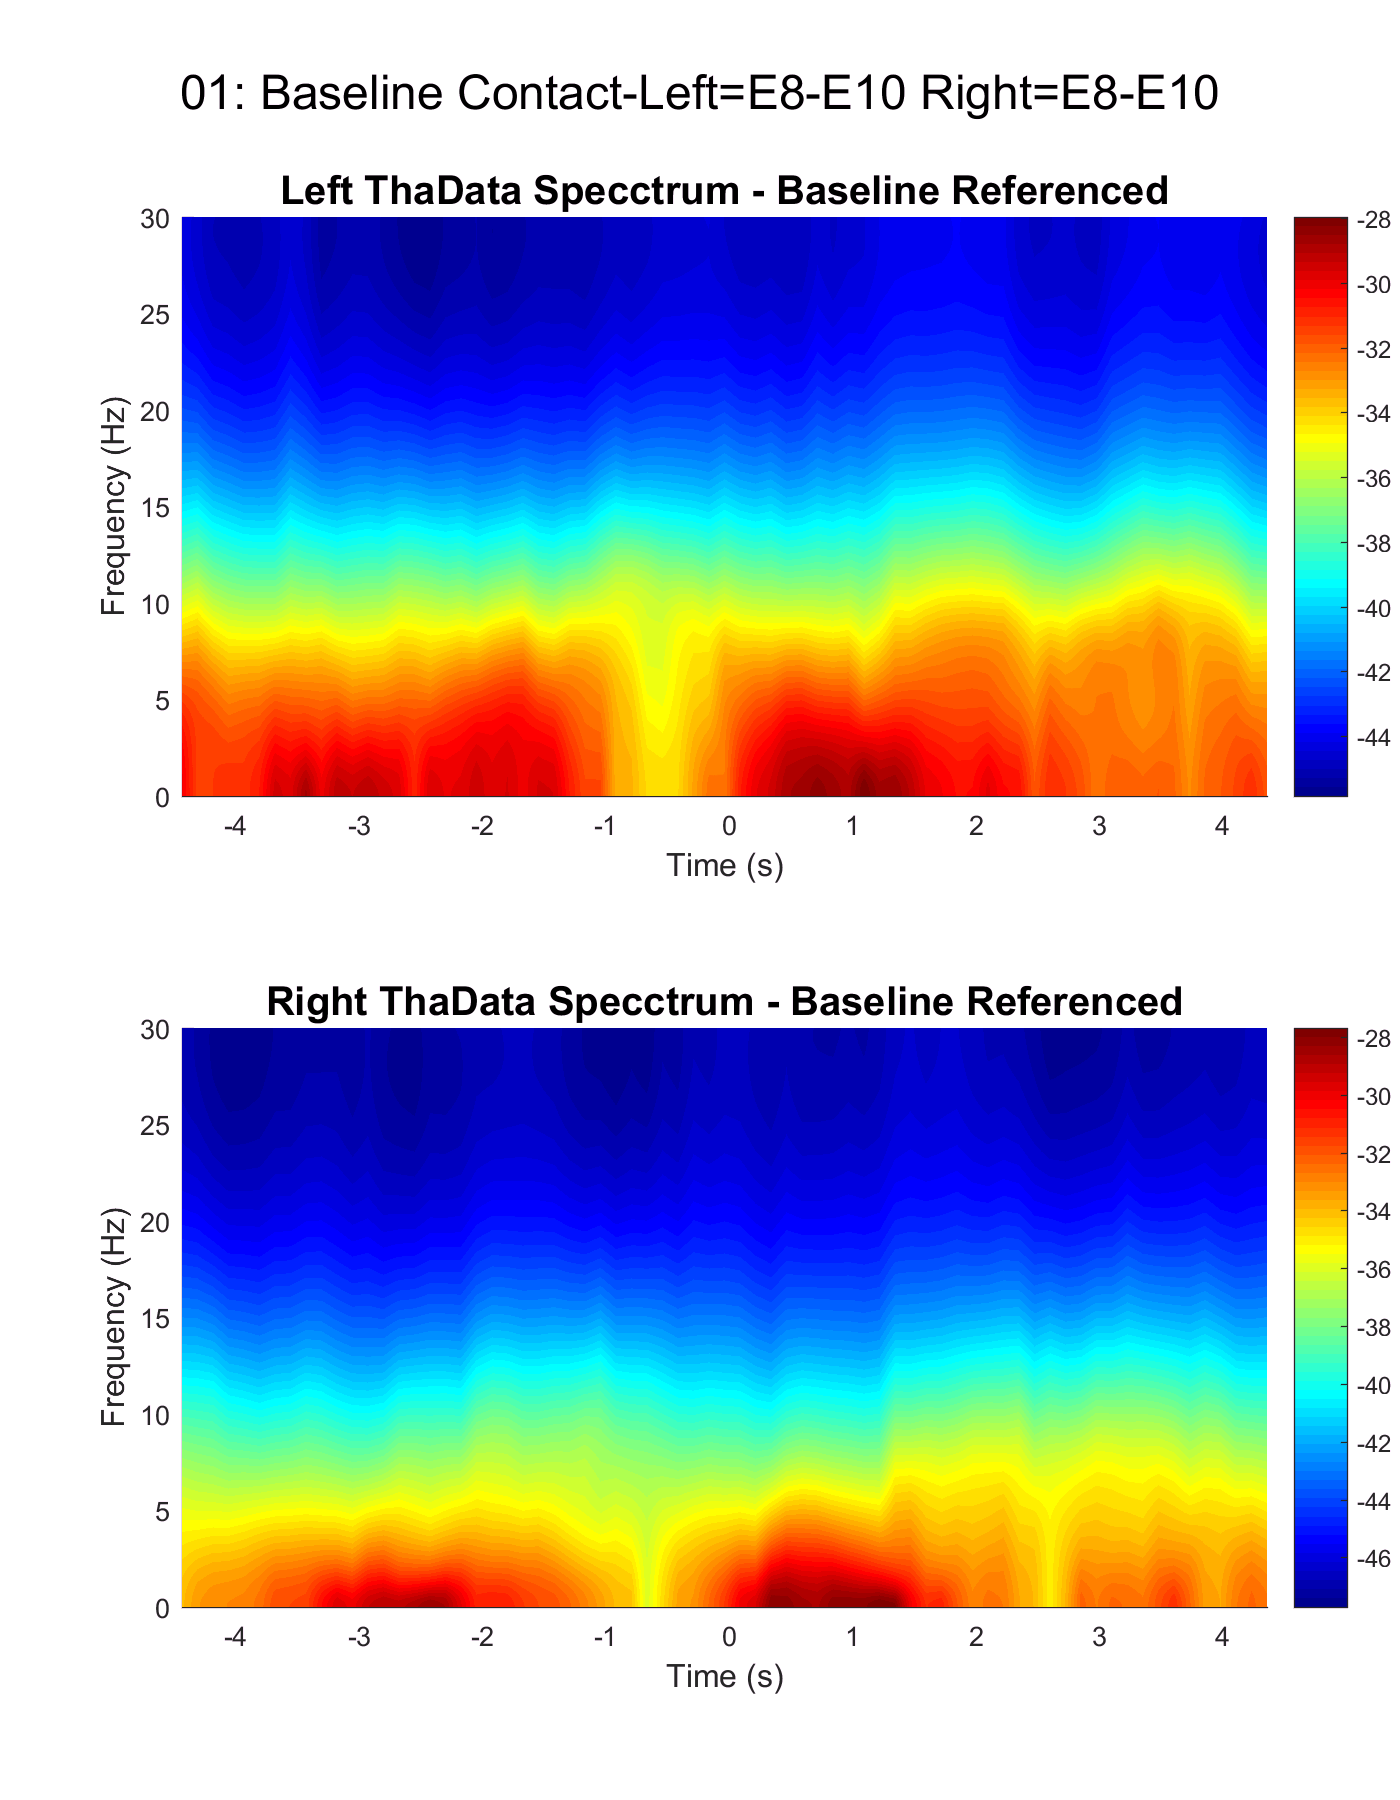

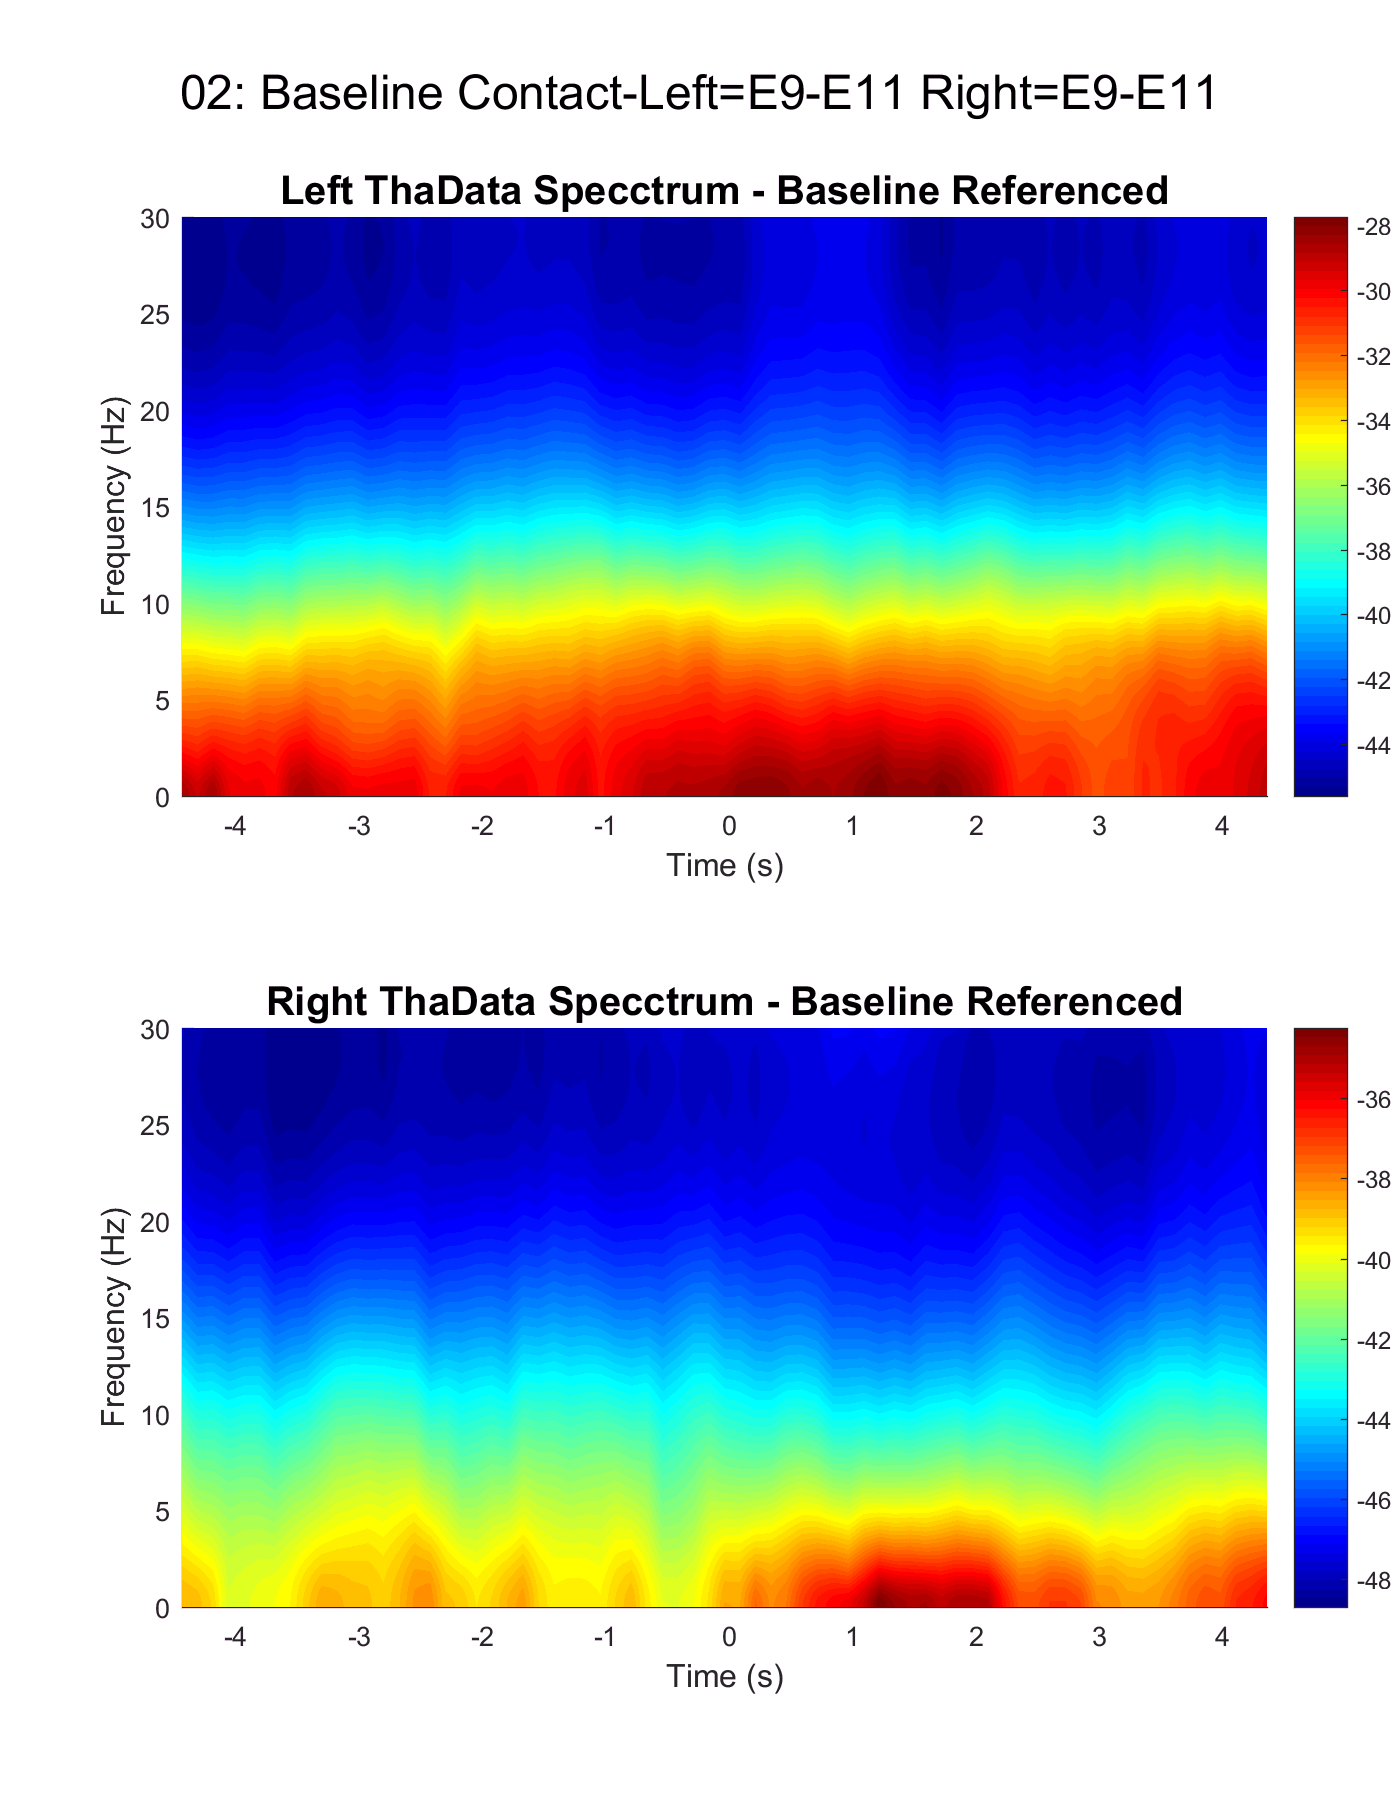

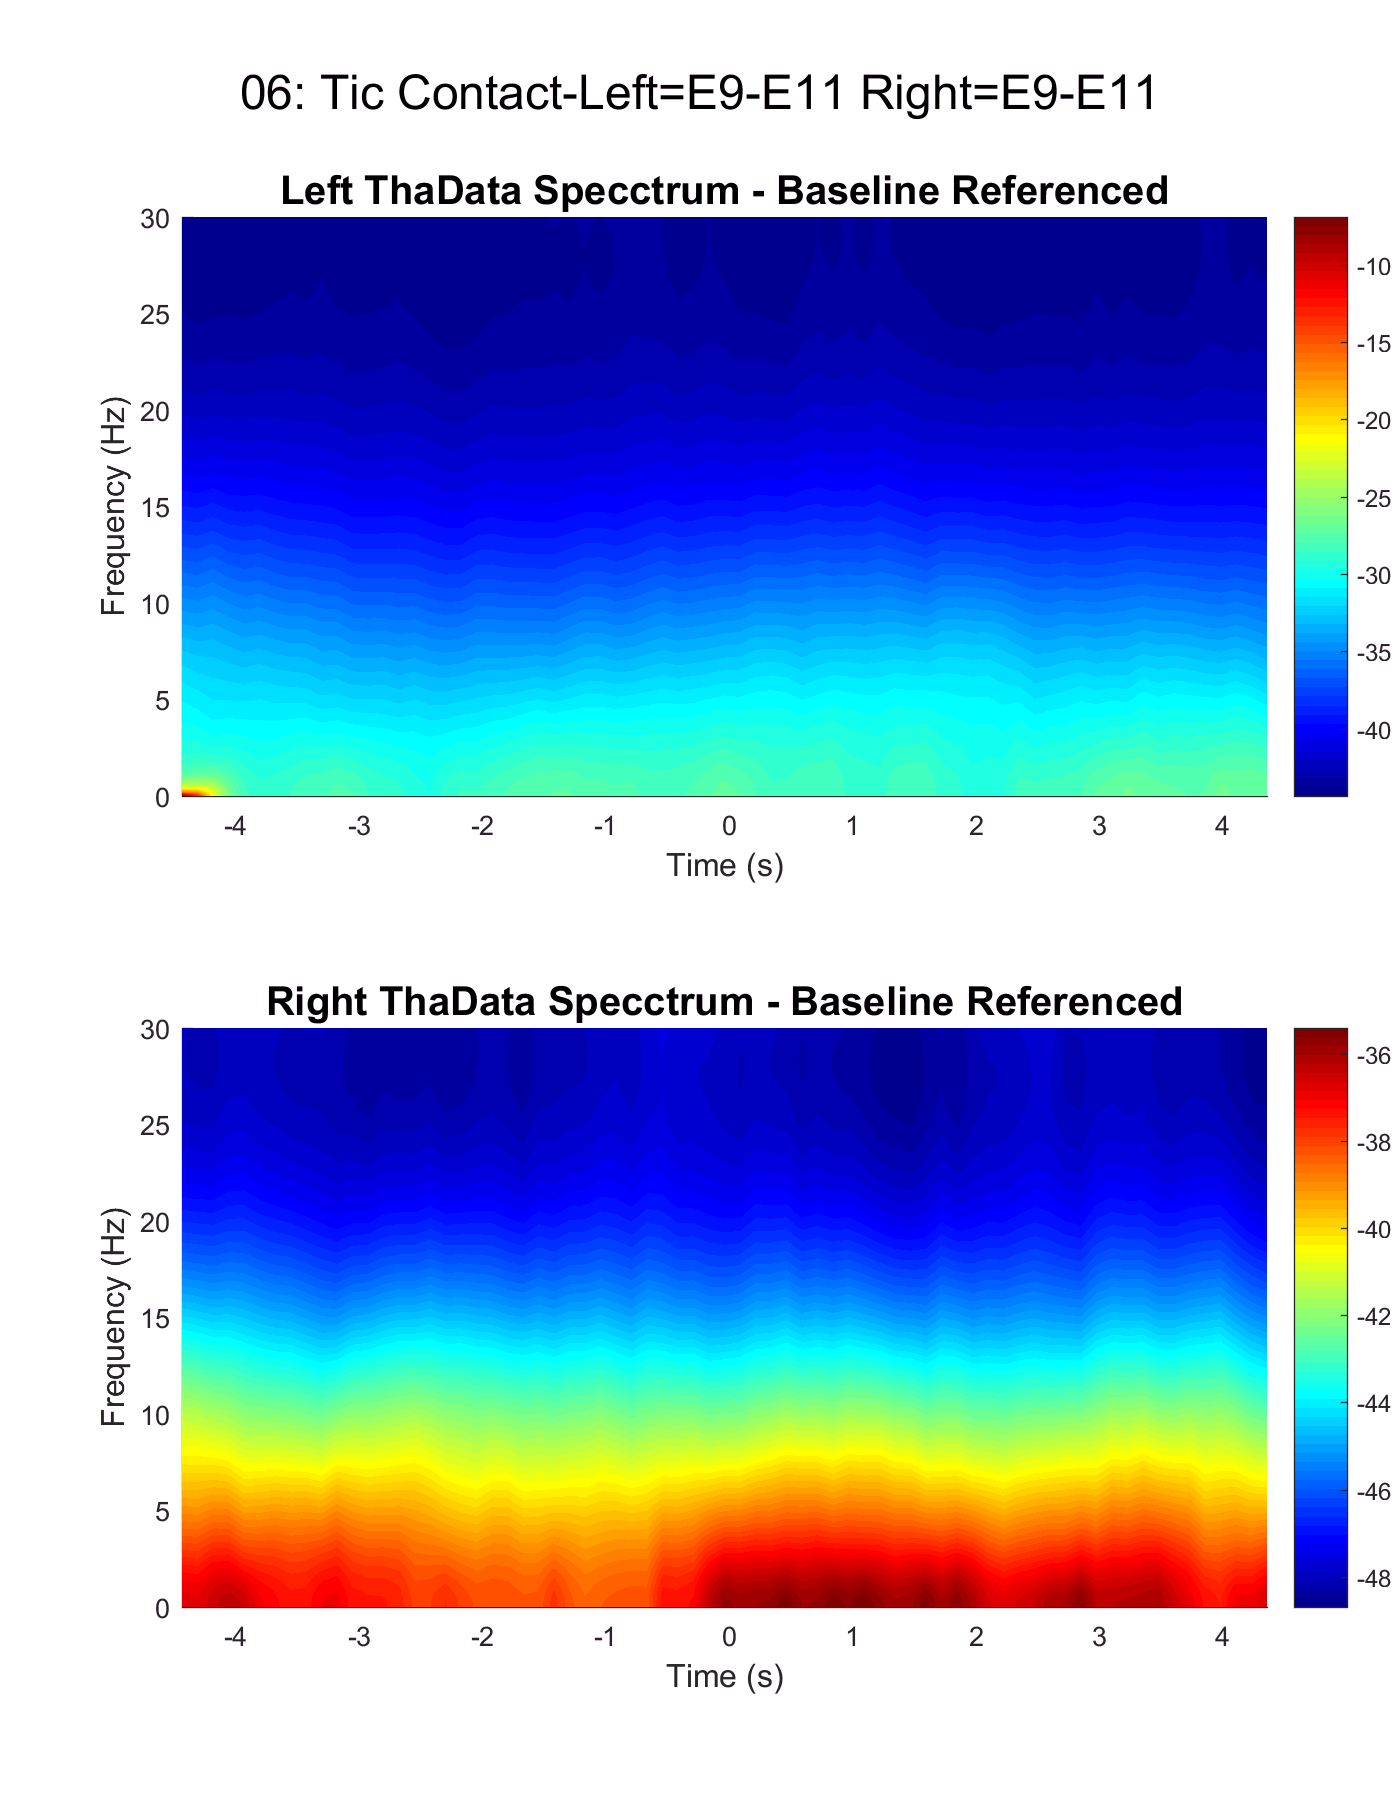

FIGURE_TYPE = 2;

Corresponding_Baseline_Index = [2,3,3,2,2,3];
for trial = [1,2,6]
    
    LeftSide = [ProcessedData(trial).Left_DBS.config.RecordingItem.SenseChannelConfig.Channel3.PlusInput,'-',ProcessedData(trial).Left_DBS.config.RecordingItem.SenseChannelConfig.Channel3.MinusInput];
    RightSide = [ProcessedData(trial).Right_DBS.config.RecordingItem.SenseChannelConfig.Channel3.PlusInput,'-',ProcessedData(trial).Right_DBS.config.RecordingItem.SenseChannelConfig.Channel3.MinusInput];
    
    LeftData = Spect_Left{trial}(:,:,~TicRecording(trial).Rejection);
    RightData = Spect_Right{trial}(:,:,~TicRecording(trial).Rejection);
    Limits = calibrateLimits(10*log10(mean(RightData,3)),10*log10(mean(LeftData,3)));
    
    %refSpectL = removeBaseline(mean(LeftData,3), Baseline(Corresponding_Baseline_Index(trial)).Left);
    %refSpectR = removeBaseline(mean(RightData,3), Baseline(Corresponding_Baseline_Index(trial)).Right);
    %refLimits = calibrateLimits(10*log10(refSpectL),10*log10(refSpectR));
    %defaultLimits = calibrateLimits(mean(LeftData,3), mean(RightData,3));
    
    %Left_Sig = testSignificance(10*log10(removeBaseline(LeftData,Baseline(Corresponding_Baseline_Index(trial)).Left)));
    %Right_Sig = testSignificance(10*log10(removeBaseline(RightData,Baseline(Corresponding_Baseline_Index(trial)).Right)));
    
    switch FIGURE_TYPE
        case 1
            largeFigure(0, [1500 900]); clf; colormap jet;
            subplot(2,2,1); cla; hold on;
            surf(T-5, Frequency, 1 - Left_Sig); shading('interp'); view(2);
            xlim([min(T-5),max(T-5)]); addColorbar('Power');
            xlabel('Time (s)','fontsize',12); 
            ylabel('Frequency (Hz)','fontsize',12);
            caxis([0.90 1]);
            title(['Left ',(SignalType),' Specctrum - Significance'],'fontsize',15);
            
            subplot(2,2,3); cla; hold on;
            surf(T-5, Frequency, 1 - Right_Sig); shading('interp'); view(2);
            xlim([min(T-5),max(T-5)]); addColorbar('Power');
            xlabel('Time (s)','fontsize',12); 
            ylabel('Frequency (Hz)','fontsize',12);
            caxis([0.90 1]);
            title(['Right ',(SignalType),' Specctrum - Significance'],'fontsize',15);
            
            subplot(2,2,2); cla; hold on;
            surf(T-5, Frequency, 10*log10(refSpectL)); shading('interp'); view(2);
            xlim([min(T-5),max(T-5)]); addColorbar('Power');
            xlabel('Time (s)','fontsize',12); 
            ylabel('Frequency (Hz)','fontsize',12);
            caxis([-max(abs(refLimits)) max(abs(refLimits))]);
            title(['Left ',(SignalType),' Specctrum - Baseline Referenced'],'fontsize',15);
            
            subplot(2,2,4); cla; hold on;
            surf(T-5, Frequency, 10*log10(refSpectL)); shading('interp'); view(2);
            xlim([min(T-5),max(T-5)]); addColorbar('Power');
            xlabel('Time (s)','fontsize',12); 
            ylabel('Frequency (Hz)','fontsize',12);
            caxis([-max(abs(refLimits)) max(abs(refLimits))]);
            title(['Right ',(SignalType),' Specctrum - Baseline Referenced'],'fontsize',15);
        
        case 2
            largeFigure(0, [700 900]); clf; colormap jet;
            subplot(2,1,1); cla; hold on;
            surf(T-5, Frequency, 10*log10(mean(LeftData,3))); shading('interp'); view(2);
            xlim([min(T-5),max(T-5)]); addColorbar('Power');
            xlabel('Time (s)','fontsize',12); 
            ylabel('Frequency (Hz)','fontsize',12);
            %caxis(defaultLimits);
            title(['Left ',(SignalType),' Specctrum - Baseline Referenced'],'fontsize',15);
            
            subplot(2,1,2); cla; hold on;
            surf(T-5, Frequency, 10*log10(mean(RightData,3))); shading('interp'); view(2);
            xlim([min(T-5),max(T-5)]); addColorbar('Power');
            xlabel('Time (s)','fontsize',12); 
            ylabel('Frequency (Hz)','fontsize',12);
            %caxis(defaultLimits);
            title(['Right ',(SignalType),' Specctrum - Baseline Referenced'],'fontsize',15);
    end
    
    suptitle(sprintf('%.2d: %s Contact-Left=%s Right=%s',trial,TaskID{trial},LeftSide,RightSide),18);
end

## Correlation of Spectral Band

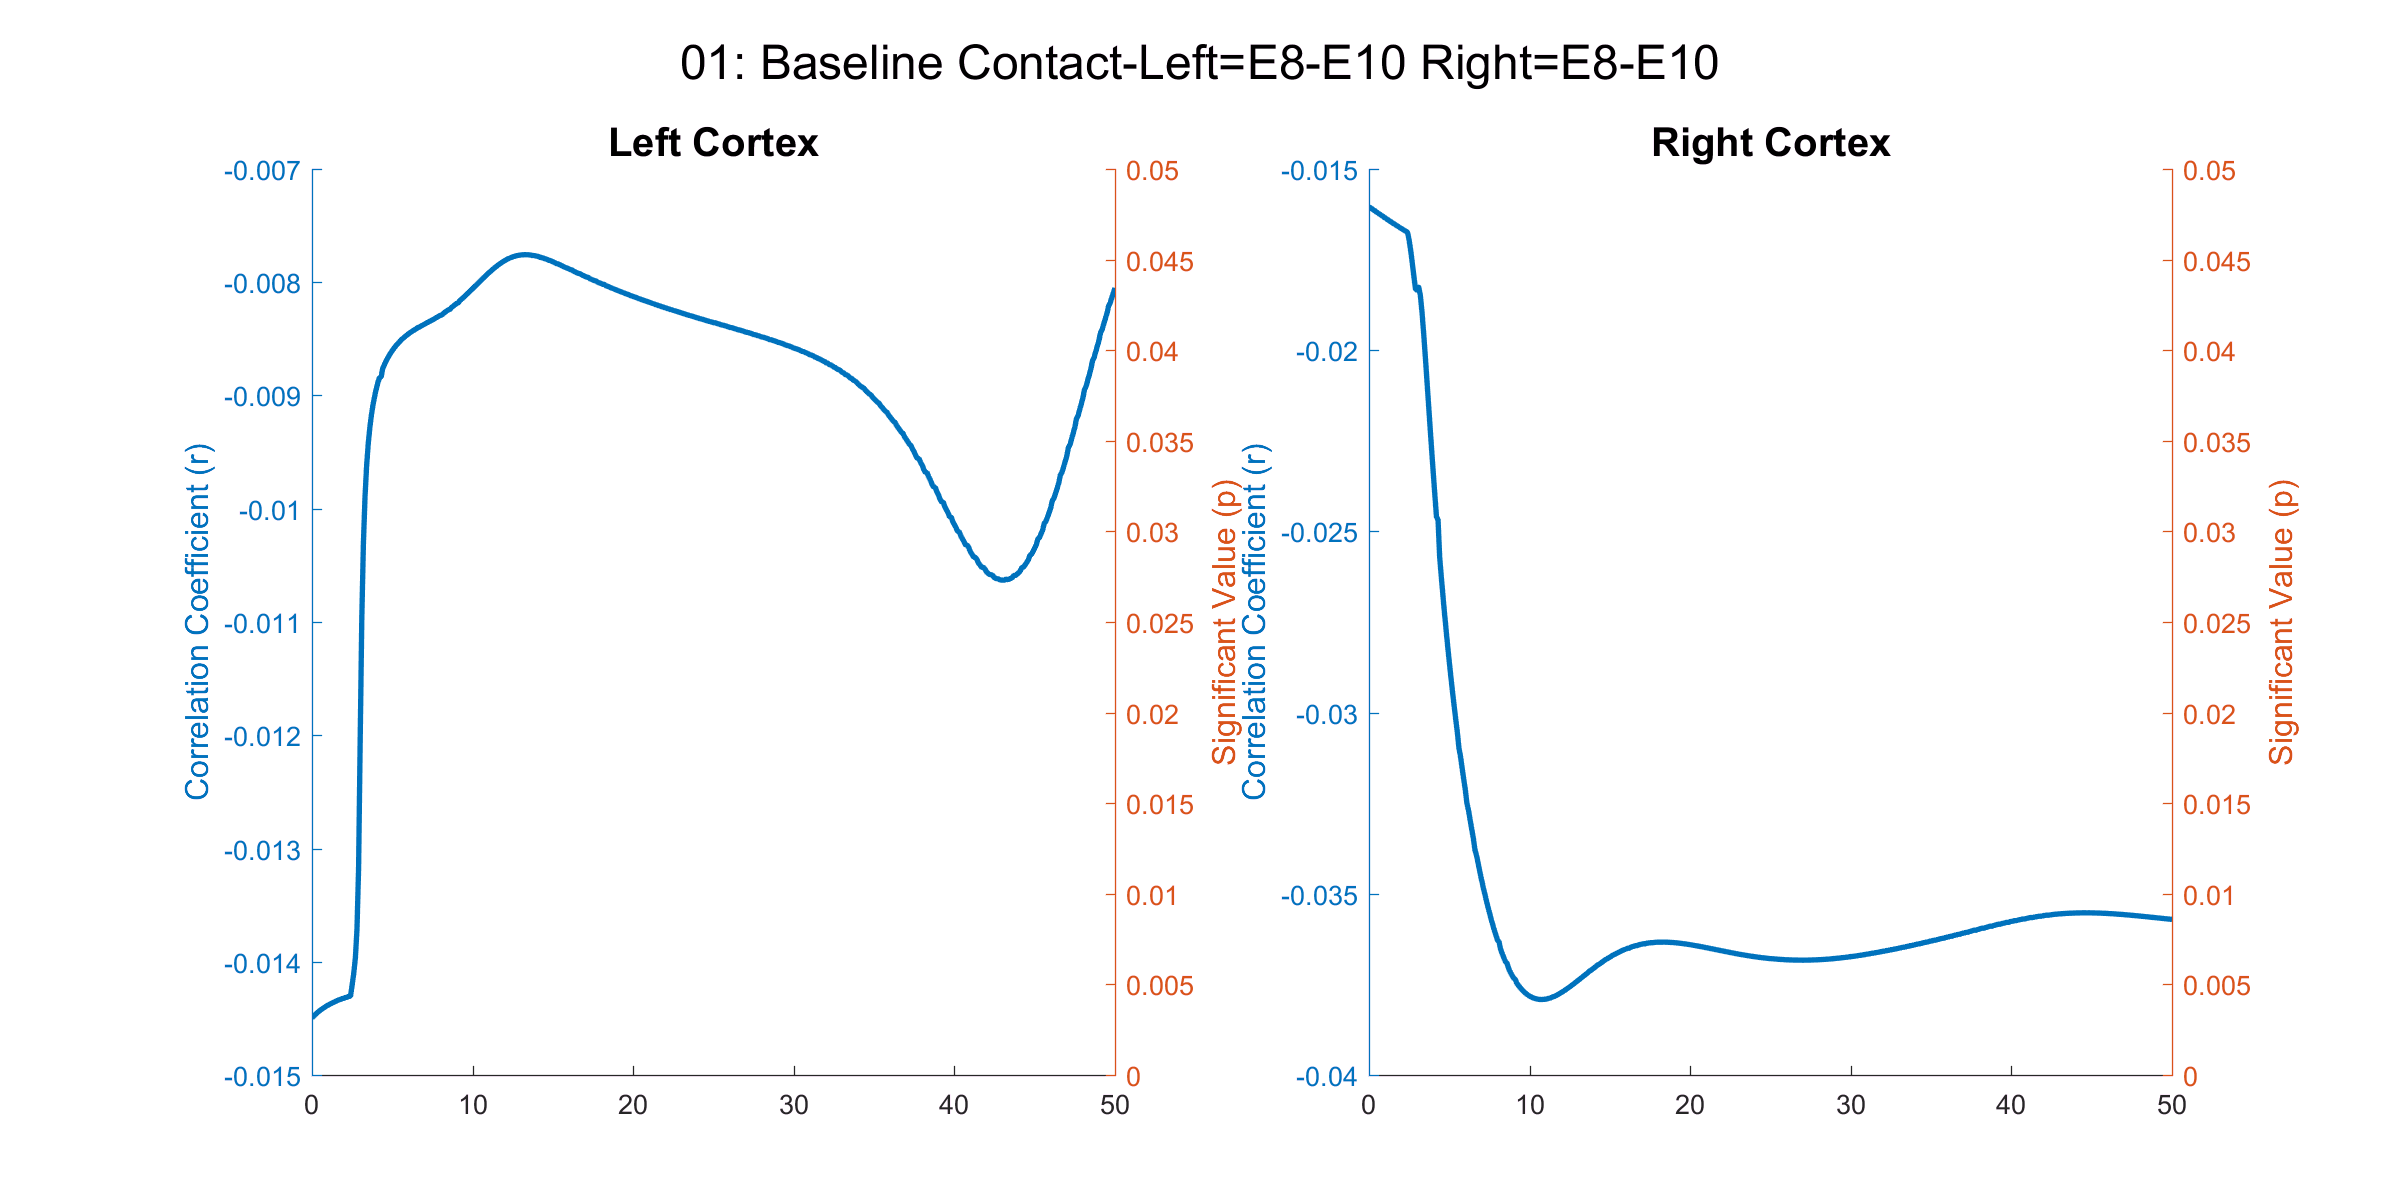

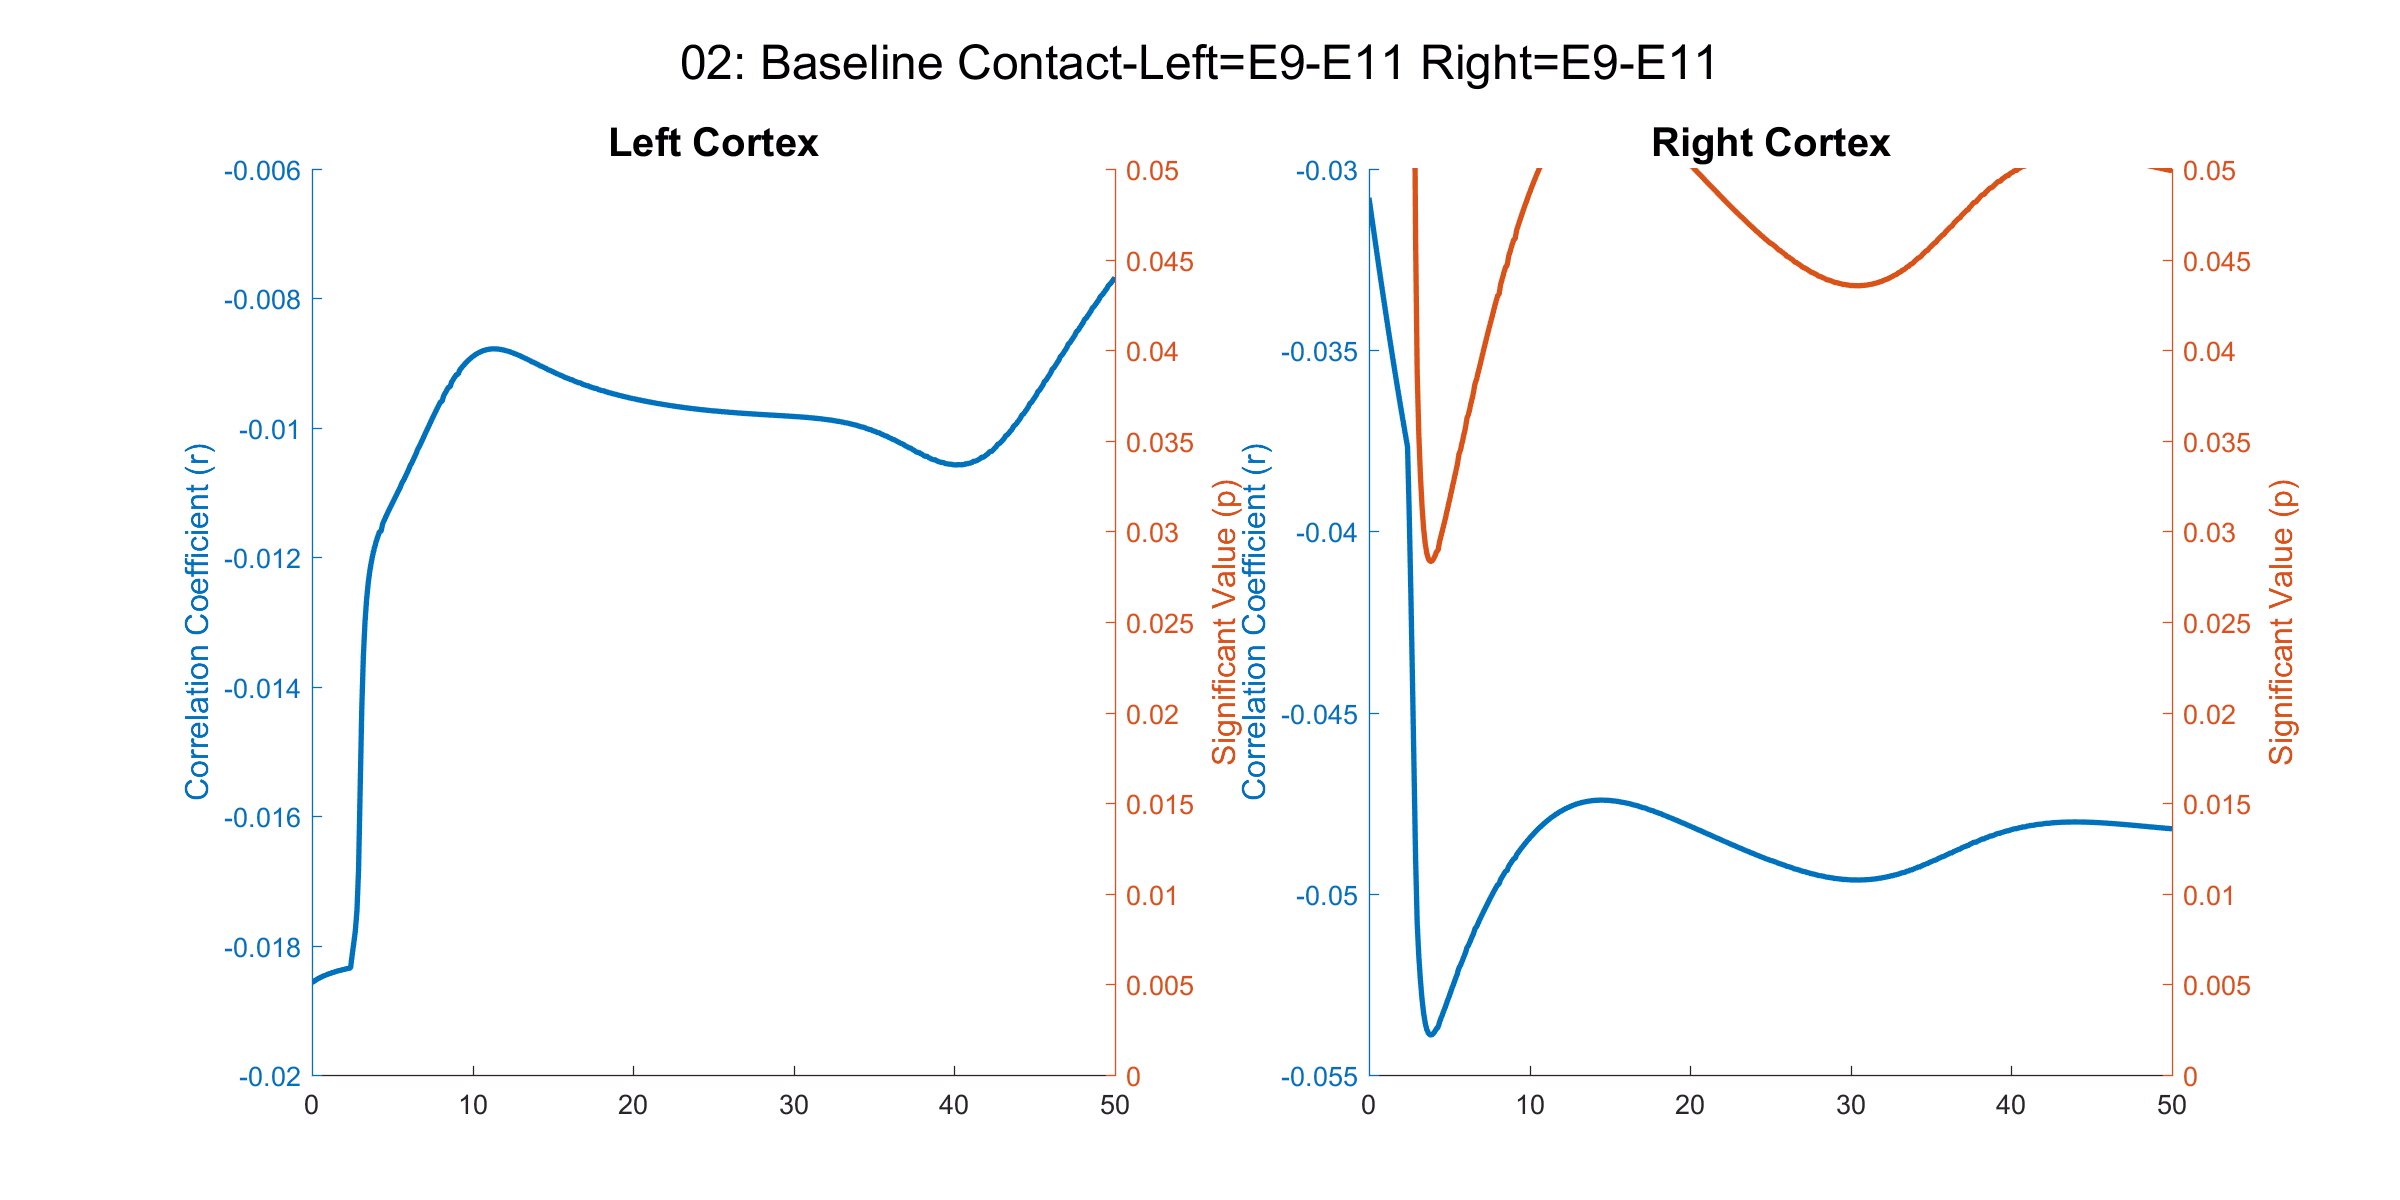

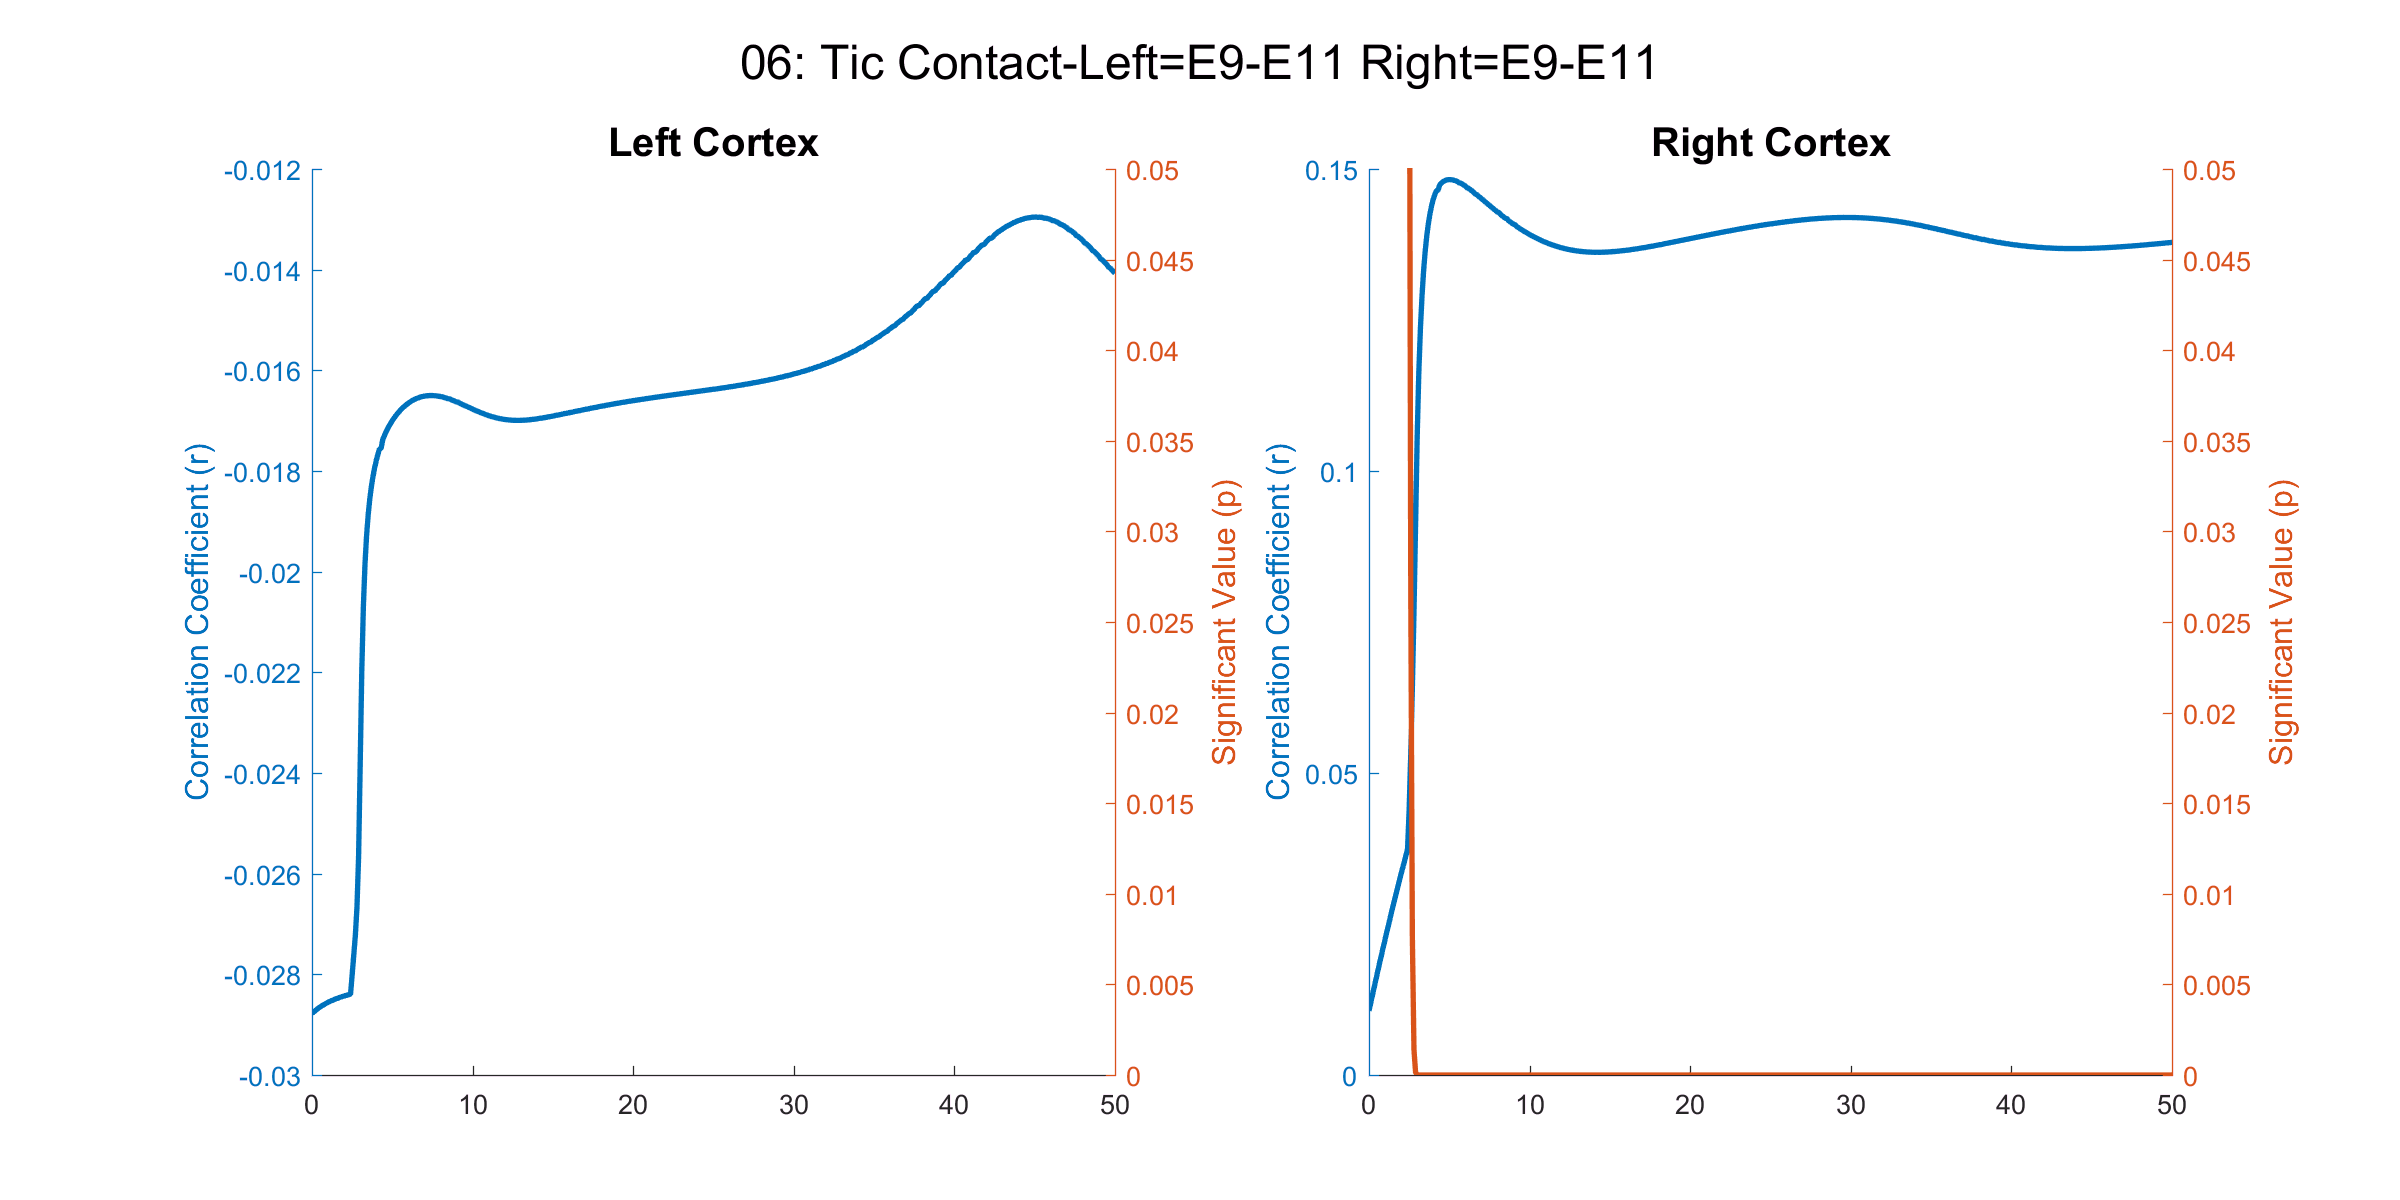

Bin = [-3 2];
DataRegion = cell(1,6);
DataRegion{1} = [80 100; 55 75];
DataRegion{2} = [100 120; 75 105];
DataRegion{6} = [70 90; 60 80];
Frequency = 0:0.1:80;
CenterFreq = 0:0.1:50;
if strcmp(SignalType,'CorData')
    Channel = 3;
else
    Channel = 1;
end

for trial = [1,2,6]
    Fs = ProcessedData(trial).Left_DBS.SamplingRate;
    Window = Fs; 
    Overlap = Fs/8*7;
    [~,~,Time_Left,Spect_Left] = MemSpect(ProcessedData(trial).Left_DBS.data(:,Channel), Window, Overlap, Frequency, Fs);
    [~,~,Time_Right,Spect_Right] = MemSpect(ProcessedData(trial).Right_DBS.data(:,Channel), Window, Overlap, Frequency, Fs);
    
    HitRegion = zeros(size(Time_Left));
    TicOnset = TicRecording(trial).Onset(~TicRecording(trial).Rejection);
    for TicID = 1:length(TicOnset)
        HitRegion(Time_Left - ProcessedData(trial).DBS_Bias(1) > TicOnset(TicID)+Bin(1) & Time_Left - ProcessedData(trial).DBS_Bias(1) < TicOnset(TicID)+Bin(2)) = 1;
    end
    
    DataRegion_Selection = Time_Left - ProcessedData(trial).DBS_Bias(1) < DataRegion{trial}(1,1) | Time_Left - ProcessedData(trial).DBS_Bias(1) > DataRegion{trial}(1,2);
    CorrelationCoe = 0;
    CorrelationSig = 0;
    count = 1;
    for Freq = CenterFreq
        BandPower = mean(Spect_Left(Frequency < Freq + 2.5 & Frequency > Freq - 2.5, :),1);
        [CorrelationCoe(count,1),CorrelationSig(count,1)] = corr(HitRegion(DataRegion_Selection)', BandPower(DataRegion_Selection)');
        count = count + 1;
    end
    
    largeFigure(0, [1200 600]); clf;
    subplot(1,2,1); cla; hold on;
    yyaxis left;
    plot(CenterFreq, CorrelationCoe,'linewidth',2);
    ylabel('Correlation Coefficient (r)', 'fontsize',12);
    yyaxis right;
    plot(CenterFreq, CorrelationSig,'linewidth',2);
    ylabel('Significant Value (p)', 'fontsize',12);
    ylim([0 0.05]);
    title('Left Cortex','fontsize',15);
    
    HitRegion = zeros(size(Time_Right));
    TicOnset = TicRecording(trial).Onset(~TicRecording(trial).Rejection);
    for TicID = 1:length(TicOnset)
        HitRegion(Time_Right - ProcessedData(trial).DBS_Bias(2) > TicOnset(TicID)+Bin(1) & Time_Right - ProcessedData(trial).DBS_Bias(2) < TicOnset(TicID)+Bin(2)) = 1;
    end
    
    DataRegion_Selection = Time_Right - ProcessedData(trial).DBS_Bias(2) < DataRegion{trial}(2,1) | Time_Right - ProcessedData(trial).DBS_Bias(2) > DataRegion{trial}(2,2);
    CorrelationCoe = 0;
    CorrelationSig = 0;
    count = 1;
    for Freq = CenterFreq
        BandPower = mean(Spect_Left(Frequency < Freq + 2.5 & Frequency > Freq - 2.5, :),1);
        [CorrelationCoe(count,1),CorrelationSig(count,1)] = corr(HitRegion(DataRegion_Selection)', BandPower(DataRegion_Selection)');
        count = count + 1;
    end
    
    subplot(1,2,2); cla; hold on;
    yyaxis left;
    plot(CenterFreq, CorrelationCoe,'linewidth',2);
    ylabel('Correlation Coefficient (r)', 'fontsize',12);
    yyaxis right;
    plot(CenterFreq, CorrelationSig,'linewidth',2);
    ylabel('Significant Value (p)', 'fontsize',12);
    ylim([0 0.05]);
    title('Right Cortex','fontsize',15);
    
    LeftSide = [ProcessedData(trial).Left_DBS.config.RecordingItem.SenseChannelConfig.Channel3.PlusInput,'-',ProcessedData(trial).Left_DBS.config.RecordingItem.SenseChannelConfig.Channel3.MinusInput];
    RightSide = [ProcessedData(trial).Right_DBS.config.RecordingItem.SenseChannelConfig.Channel3.PlusInput,'-',ProcessedData(trial).Right_DBS.config.RecordingItem.SenseChannelConfig.Channel3.MinusInput];
    suptitle(sprintf('%.2d: %s Contact-Left=%s Right=%s',trial,TaskID{trial},LeftSide,RightSide),18);
end

## Correlation Scatter Plot at Specific Frequency Band

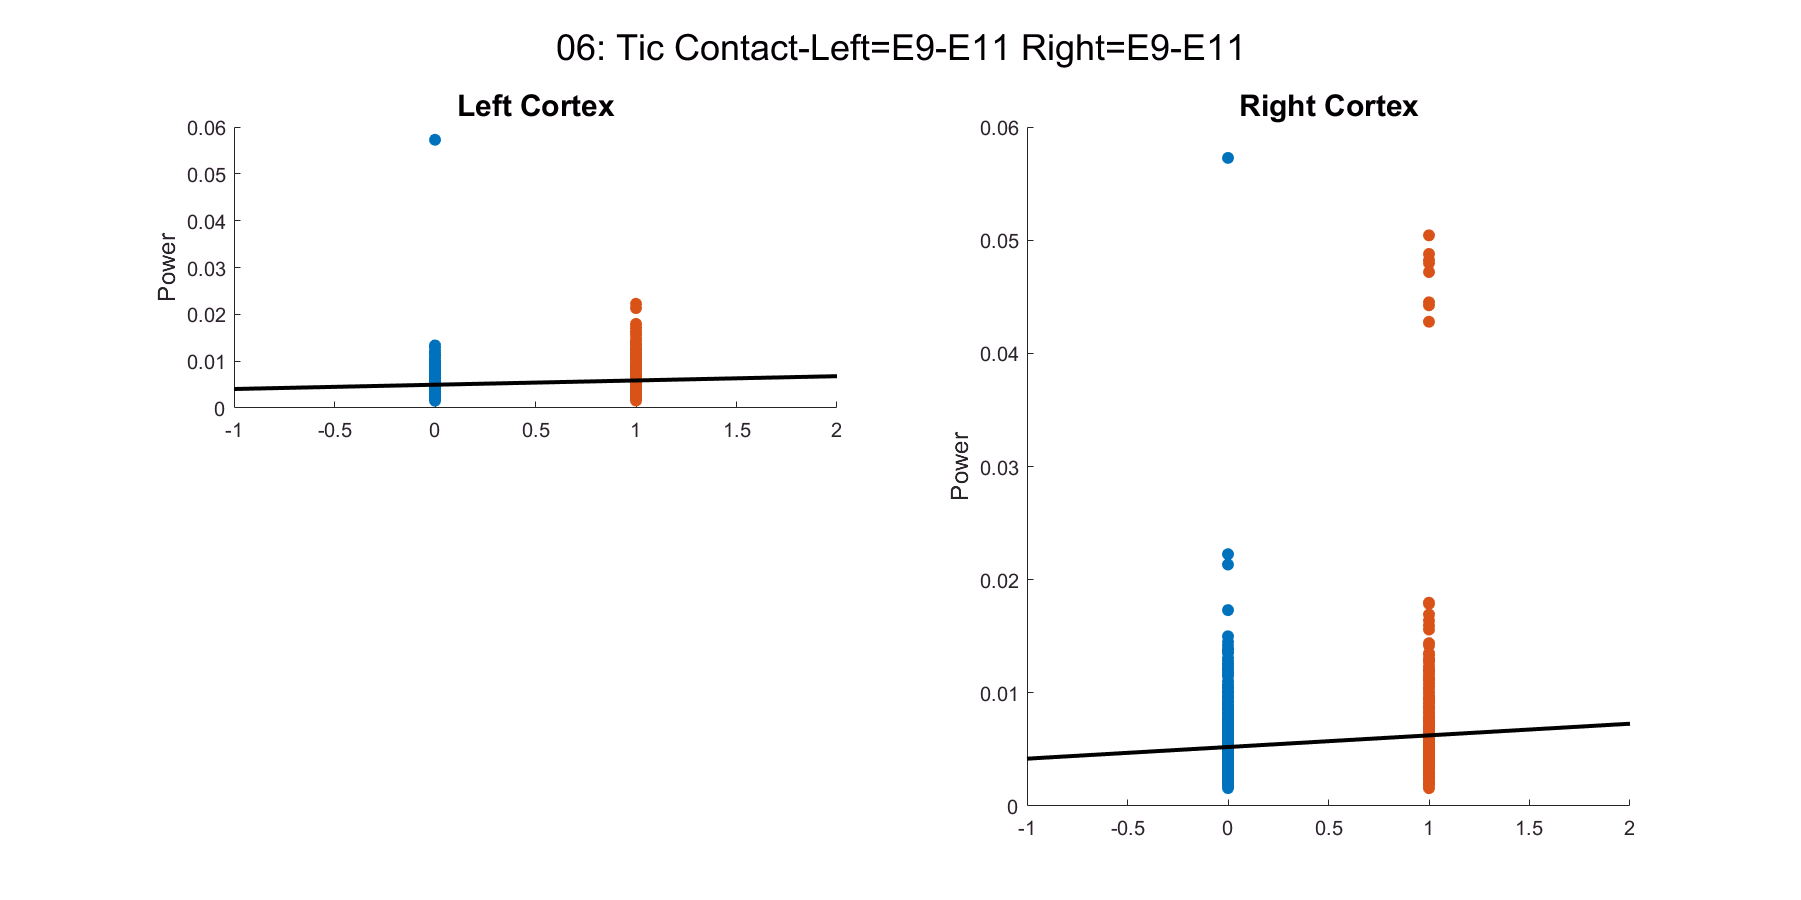

Bin = [-3 2];
DataRegion = cell(1,6);
DataRegion{1} = [80 100; 55 75];
DataRegion{2} = [100 120; 75 105];
DataRegion{6} = [70 90; 60 80];
Frequency = 0:0.1:80;

CenterFreq_Specific = [20,30,20,30,20,12;
                       10,10,15,15,15,15];

for trial = 6
    Fs = ProcessedData(trial).Left_DBS.SamplingRate;
    Window = Fs; 
    Overlap = Fs/8*7;
    [~,~,Time_Left,Spect_Left] = MemSpect(ProcessedData(trial).Left_DBS.data(:,3), Window, Overlap, Frequency, Fs);
    [~,~,Time_Right,Spect_Right] = MemSpect(ProcessedData(trial).Right_DBS.data(:,3), Window, Overlap, Frequency, Fs);
    
    HitRegion = zeros(size(Time_Left));
    TicOnset = TicRecording(trial).Onset(~TicRecording(trial).Rejection);
    for TicID = 1:length(TicOnset)
        HitRegion(Time_Left - ProcessedData(trial).DBS_Bias(1) > TicOnset(TicID)+Bin(1) & Time_Left - ProcessedData(trial).DBS_Bias(1) < TicOnset(TicID)+Bin(2)) = 1;
    end
    
    DataRegion_Selection = Time_Left - ProcessedData(trial).DBS_Bias(1) < DataRegion{trial}(1,1) | Time_Left - ProcessedData(trial).DBS_Bias(1) > DataRegion{trial}(1,2);
    
    Freq = CenterFreq_Specific(1,trial);
    BandPower = mean(Spect_Left(Frequency < Freq + 2.5 & Frequency > Freq - 2.5, :),1);
    [CorrelationCoe,CorrelationSig] = corr(HitRegion(DataRegion_Selection)', BandPower(DataRegion_Selection)');
    LinearRegression = polyfit(HitRegion(DataRegion_Selection)', BandPower(DataRegion_Selection)',1);
    
    largeFigure(0, [1200 600]); clf; hold on;
    subplot(1,2,1); cla; hold on;
    X = HitRegion(DataRegion_Selection);
    Y = BandPower(DataRegion_Selection);
    scatter(zeros(sum(X==0),1),Y(X==0),'filled');
    scatter(ones(sum(X==1),1),Y(X==1),'filled');
    plot(-1:0.1:2, (-1:0.1:2)*LinearRegression(1)+LinearRegression(2), 'k', 'linewidth', 2);
    ylabel('Power', 'fontsize',12);
    title('Left Cortex','fontsize',15);
    
    HitRegion = zeros(size(Time_Right));
    TicOnset = TicRecording(trial).Onset(~TicRecording(trial).Rejection);
    for TicID = 1:length(TicOnset)
        HitRegion(Time_Right - ProcessedData(trial).DBS_Bias(2) > TicOnset(TicID)+Bin(1) & Time_Right - ProcessedData(trial).DBS_Bias(2) < TicOnset(TicID)+Bin(2)) = 1;
    end
    
    DataRegion_Selection = Time_Right - ProcessedData(trial).DBS_Bias(2) < DataRegion{trial}(2,1) | Time_Right - ProcessedData(trial).DBS_Bias(2) > DataRegion{trial}(2,2);
    Freq = CenterFreq_Specific(1,trial);
    BandPower = mean(Spect_Left(Frequency < Freq + 2.5 & Frequency > Freq - 2.5, :),1);
    [CorrelationCoe,CorrelationSig] = corr(HitRegion(DataRegion_Selection)', BandPower(DataRegion_Selection)');
    LinearRegression = polyfit(HitRegion(DataRegion_Selection)', BandPower(DataRegion_Selection)',1);
    
    subplot(1,2,2); cla; hold on;
    X = HitRegion(DataRegion_Selection);
    Y = BandPower(DataRegion_Selection);
    scatter(zeros(sum(X==0),1),Y(X==0),'filled');
    scatter(ones(sum(X==1),1),Y(X==1),'filled');
    plot(-1:0.1:2, (-1:0.1:2)*LinearRegression(1)+LinearRegression(2), 'k', 'linewidth', 2);
    ylabel('Power', 'fontsize',12);
    title('Right Cortex','fontsize',15);
    
    LeftSide = [ProcessedData(trial).Left_DBS.config.RecordingItem.SenseChannelConfig.Channel3.PlusInput,'-',ProcessedData(trial).Left_DBS.config.RecordingItem.SenseChannelConfig.Channel3.MinusInput];
    RightSide = [ProcessedData(trial).Right_DBS.config.RecordingItem.SenseChannelConfig.Channel3.PlusInput,'-',ProcessedData(trial).Right_DBS.config.RecordingItem.SenseChannelConfig.Channel3.MinusInput];
    suptitle(sprintf('%.2d: %s Contact-Left=%s Right=%s',trial,TaskID{trial},LeftSide,RightSide),18);
end

## Detection Program

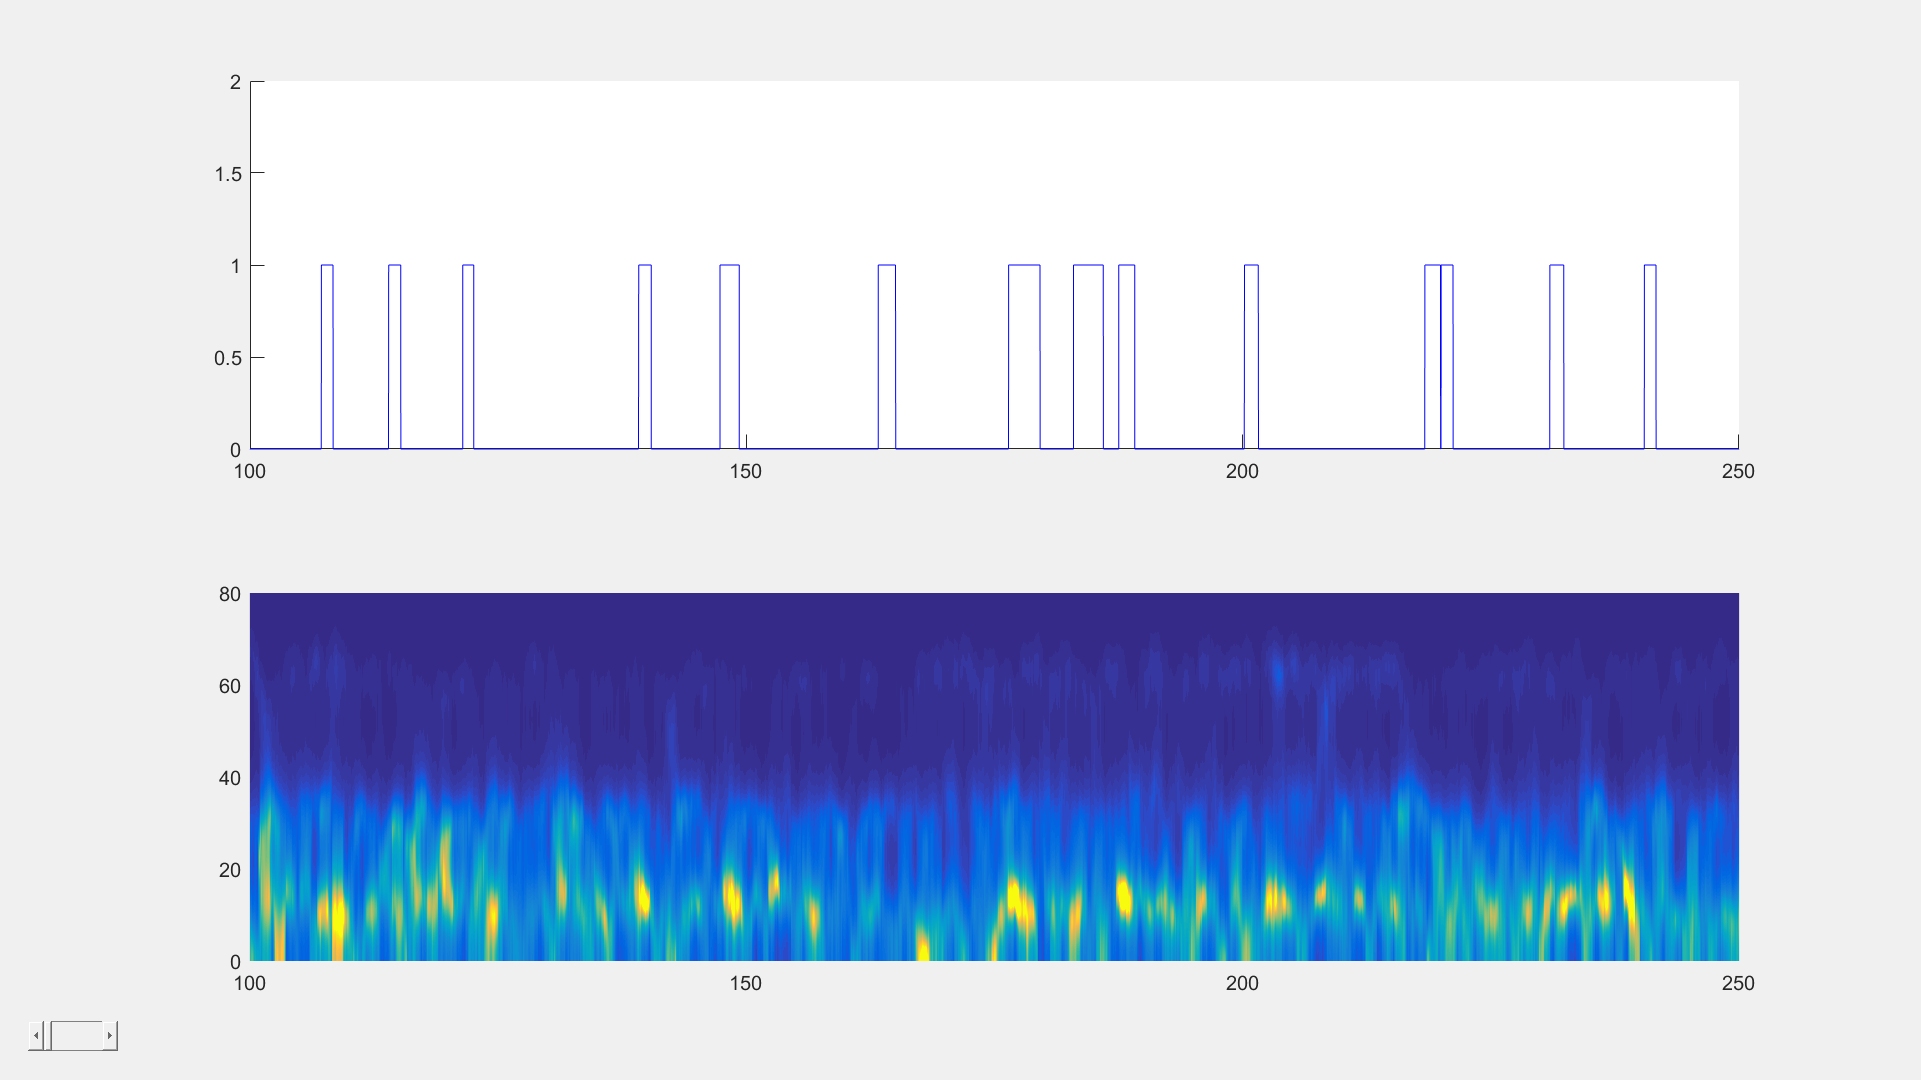

Data = ProcessedData(6);
TicData = TicRecording(6);

Frequency = 0:0.1:80;
Fs = Data.Left_DBS.SamplingRate;
Window = Fs; 
Overlap = Fs/8*7;
[~,~,Time_Left,Spect_Left] = MemSpect(Data.Left_DBS.data(:,3), Window, Overlap, Frequency, Fs);
    
% Left Cortex
largeFigure(0, [1280 720]); clf;
subplot(2,1,1); cla; hold on;
plot(Data.Marker.time - Data.EMG_Bias, Data.Marker.data > 0, 'b');
axis([100 250 0 2]); 
subplot(2,1,2); cla; hold on;
surf(Time_Left - Data.DBS_Bias(1), Frequency, Spect_Left); shading('interp'); view(2);
Left_Limits = calibrateLimits(Spect_Left,Spect_Left);
xlim([100 250]);
caxis(Left_Limits);